### Timings for kernel

format shortE

t3_DO = [0.00018100, 0.00018900, 0.00018200, 0.00018700, 0.00020200];
t3_AB = [0.00014200, 0.00012100, 0.00013200, 0.00011700, 0.00016500];
t3_AB_A = [0.00001400, 0.00002700, 0.00002700, 0.00002700, 0.00001400];
t3_ABA = t3_AB_A + t3_AB;

t8_DO = [0.00019500, 0.00020500, 0.00020200, 0.00016700, 0.00019200];
t8_AB = [0.00013300, 0.00013500, 0.00013400, 0.00012700, 0.00013100];
t8_AB_A = [0.00003800, 0.00004600, 0.00001400, 0.00001500, 0.00003700];
t8_ABA = t8_AB_A + t8_AB;

t12_DO = [0.00019600,  0.0001700, 0.00017300, 0.00020400, 0.00018700];
t12_AB = [0.00013300, 0.00011100, 0.00010600, 0.00013300, 0.00011000];
t12_AB_A = [0.00003700, 0.00002900, 0.00001700, 0.00004500, 0.00002900];
t12_ABA = t12_AB_A + t12_AB;

t16_DO = [0.00018900, 0.00020900, 0.00021100, 0.00020400, 0.00020500];
t16_AB = [0.00011800, 0.00013800, 0.00013900, 0.00013600, 0.00013800];
t16_AB_A = [0.00003100, 0.00001700, 0.00001800, 0.00001700, 0.00001800];
t16_ABA = t16_AB_A + t16_AB;

t32_DO = [0.00023700, 0.00024500, 0.00026600, 0.00020700, 0.00024800];
t32_AB = [0.00013200, 0.00013500, 0.00017500, 0.00013700, 0.00016300];
t32_AB_A = [0.00003500, 0.00004900, 0.00004000, 0.00003500, 0.00003500];
t32_ABA = t32_AB_A + t32_AB;

t64_DO = [ 0.00097900, 0.00097400, 0.00099900, 0.00097600, 0.00100000];
t64_AB = [0.0005200, 0.00051500, 0.00053700, 0.00051700, 0.00053500];
t64_AB_A = [0.00040600, 0.00040600, 0.00040600, 0.00040600, 0.00040600];
t64_ABA = t64_AB_A + t64_AB;

t110_DO = [0.0073900, 0.00736200, 0.00736200, 0.00738300, 0.00733800];
t110_AB = [0.00372100, 0.00370100, 0.00370000, 0.00371400, 0.00370300];
t110_AB_A = [0.00356900, 0.00356100, 0.00356100, 0.00356800, 0.00353500];
t110_ABA = t110_AB_A + t110_AB;

t3_DO = mean(t3_DO);
t3_AB = mean(t3_AB);
t3_AB_A = mean(t3_AB_A);
t3_ABA = t3_AB_A + t3_AB;
t3_DTO = t3_DO - t3_ABA;

t8_DO = mean(t8_DO);
t8_AB = mean(t8_AB);
t8_AB_A = mean(t8_AB_A);
t8_ABA = t8_AB_A + t8_AB;
t8_DTO = t8_DO - t8_ABA;

t12_DO = mean(t12_DO);
t12_AB = mean(t12_AB);
t12_AB_A = mean(t12_AB_A);
t12_ABA = t12_AB_A + t12_AB;
t12_DTO = t12_DO - t12_ABA;

t16_DO = mean(t16_DO);
t16_AB = mean(t16_AB);
t16_AB_A = mean(t3_AB_A);
t16_ABA = t16_AB_A + t16_AB;
t16_DTO = t16_DO - t16_ABA;

t32_DO = mean(t32_DO);
t32_AB = mean(t32_AB);
t32_AB_A = mean(t32_AB_A);
t32_ABA = t32_AB_A + t32_AB;
t32_DTO = t32_DO - t32_ABA;

t64_DO = mean(t64_DO);
t64_AB = mean(t64_AB);
t64_AB_A = mean(t64_AB_A);
t64_ABA = t64_AB_A + t64_AB;
t64_DTO = t64_DO - t64_ABA;

t110_DO = mean(t110_DO);
t110_AB = mean(t110_AB);
t110_AB_A = mean(t110_AB_A);
t110_ABA = t110_AB_A + t110_AB;
t110_DTO = t110_DO - t110_ABA;


N = [3; 8; 12; 16; 24; 32; 48; 64; 88; 110];
WithDataOverhead = [t3_DO; t8_DO; t12_DO; t16_DO; t32_DO; t64_DO; t110_DO];
WithoutDataOverhead = [t3_ABA; t8_ABA; t12_ABA; t16_ABA; t32_ABA; t64_ABA; t110_ABA];
DataTransferOverhead = [t3_DTO; t8_DTO; t12_DTO; t16_DTO; t32_DTO; t64_DTO; t110_DTO];

results = table(N, WithDataOverhead, WithoutDataOverhead, DataTransferOverhead)

results = 7×4 table
        N         WithDataOverhead    WithoutDataOverhead    DataTransferOverhead
    __________    ________________    ___________________    ____________________

    3.0000e+00       1.8820e-04           1.5720e-04              3.1000e-05     
    8.0000e+00       1.9220e-04           1.6200e-04              3.0200e-05     
    1.2000e+01       1.8600e-04           1.5000e-04              3.6000e-05     
    1.6000e+01       2.0360e-04           1.5560e-04              4.8000e-05     
    3.2000e+01       2.4060e-04           1.8720e-04              5.3400e-05     
    6.4000e+01       9.8560e-04           9.3080e-04              5.4800e-05     
    1.1000e+02       7.3670e-03           7.2666e-03              1.0040e-04     


### Golden Measure

golden_t3 = mean([0.00000400, 0.00000400, 0.00000500, 0.00000500, 0.00000400]);
golden_t8 = mean([0.00002000, 0.00001900, 0.00001900, 0.00001800, 0.00001900]);
golden_t12 = mean([0.00005700, 0.00005700, 0.00005800, 0.00005700, 0.00005700]);
golden_t16 = mean([0.00013000, 0.00013000, 0.00013000, 0.00013000, 0.00013000]);
% golden_t24 = mean([0.00045200, 0.00043400, 0.00043200, 0.00043200, 0.00043300]);
golden_t32 = mean([0.00102000, 0.00101800, 0.00104400, 0.00101800, 0.00104200]);
% golden_t48 = mean([0.00340900, 0.00062000, 0.00340100, 0.00123300, 0.00340300]);
golden_t64 = mean([0.00821900, 0.00191800, 0.00821100, 0.00233600, 0.00224300]);
% golden_t88 = mean([0.01965800, 0.00375000, 0.01912900, 0.00375700, 0.01972600]);
golden_t110 = mean([0.01756400, 0.00776800, 0.01696400, 0.00743700, 0.01766000]);

golden_times = [golden_t3; golden_t8; golden_t12; golden_t12; golden_t32; golden_t64; golden_t110]

golden_times =    4.4000e-06
   1.9000e-05
   5.7200e-05
   5.7200e-05
   1.0284e-03
   2.0964e-03
   7.4906e-03


golden_results = table(N, golden_times)

golden_results = 7×2 table
        N         golden_times
    __________    ____________

    3.0000e+00     4.4000e-06 
    8.0000e+00     1.9000e-05 
    1.2000e+01     5.7200e-05 
    1.6000e+01     5.7200e-05 
    3.2000e+01     1.0284e-03 
    6.4000e+01     2.0964e-03 
    1.1000e+02     7.4906e-03 


### Speed-up

speedup_withDO = golden_times./WithDataOverhead;

speedup_withDO =    2.3379e-02
   9.8855e-02
   3.0753e-01
   2.8094e-01
   4.2743e+00
   2.1270e+00
   1.0168e+00


speedup_withoutDO = golden_times./WithoutDataOverhead;

speedup_withoutDO =    2.7990e-02
   1.1728e-01
   3.8133e-01
   3.6761e-01
   5.4936e+00
   2.2523e+00
   1.0308e+00


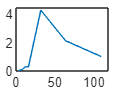


plot(N, speedup_withDO)

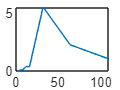

plot(N, speedup_withoutDO)